# **KUKA  Iiwa 7 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Clear the environment.

clc;
clear;
close all;

Load the KUKA Iiwa 7 rigid body tree (RBT) model.

robot_name = 'kukaIiwa7';
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot (chosen in the 2nd argument)

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

endEffector = "iiwa_link_ee_kuka"; 

Specify initial and desired end-effector poses. Use inverse kinematics (maps from pose to joint angles) to solve for the initial robot configuration given a desired pose.

% Initial end-effector pose
taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.35 0.7 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

close all;
%% Construct voxel obstacle representation for STOMP planner
% Define the workspace (the voxel world limits). Depending on the robot's reach range.
Env_size = [-1, -1, -1; 2, 2, 2];  % [xmin, ymin, zmin] for 1st row, xyz-lengths for 2nd row
voxel_size = [0.02, 0.02, 0.02];  % unit: m
% Binary map: all free space initially, 
binary_world = zeros(Env_size(2, 1) / voxel_size(1), Env_size(2, 2) / voxel_size(2), Env_size(2, 3) / voxel_size(3));
% binary_world_offset = Env_size(1, :)./ voxel_size;

%% XYZ metric representation (in meter) for each voxel 
% !!!!Watch out for the useage of meshgrid:
% [X,Y,Z] = meshgrid(x,y,z) returns 3-D grid coordinates defined by the 
% vectors x, y, and z. The grid represented by X, Y, and Z has size 
% length(y)-by-length(x)-by-length(z).
% The 3D coordinate is of the center of the voxels
[Xw, Yw, Zw] = meshgrid(Env_size(1, 1) + 0.5 * voxel_size(1) : voxel_size(1) : Env_size(1, 1) + Env_size(2, 1) - 0.5 * voxel_size(1), ...
       Env_size(1, 2) + 0.5 * voxel_size(2) : voxel_size(2) : Env_size(1, 2) + Env_size(2, 2) - 0.5 * voxel_size(2), ...
    Env_size(1, 3) + 0.5 * voxel_size(3) : voxel_size(3) : Env_size(1, 3) + Env_size(2, 3) - 0.5 * voxel_size(3));

world = {};
[world{end+1},binary_world] = addBox(binary_world, Env_size, voxel_size, 0.08*2,[0.15 0.3 0.6]);
[world{end+1},binary_world] = addBox(binary_world, Env_size, voxel_size, 0.08*2,[0.15 0.3 0.8]);
[world{end+1},binary_world] = addBox(binary_world, Env_size, voxel_size, 0.08*2,[0.4 0.5 0.6]);

volumeViewer(binary_world);

%% construct signed Euclidean Distance for the voxel world
% Only approximation if the voxel is not a cube
voxel_world_sEDT = prod(voxel_size) ^ (1/3) * sEDT_3d(binary_world);


voxel_world.voxel_size = voxel_size;
voxel_world.voxel = binary_world;
% voxel_world.offset =  binary_world_offset;
voxel_world.world_size = size(binary_world);
voxel_world.Env_size = Env_size; % in metric 
voxel_world.sEDT =  voxel_world_sEDT;


Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

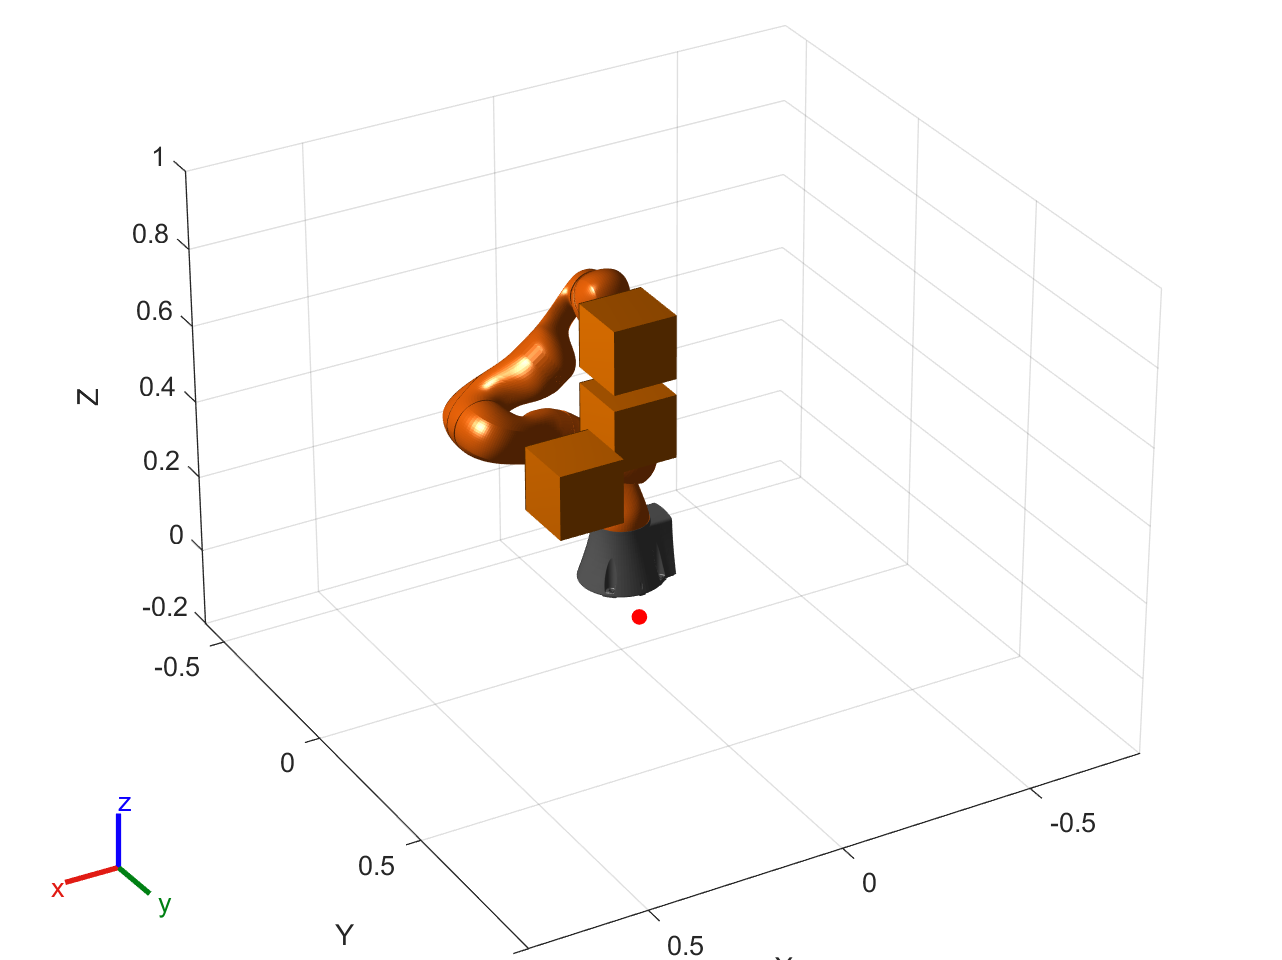

x0 = [currentRobotJConfig', zeros(1,numJoints)];

% Visualize the obstacles and robot manipulator

% Initial visualizer
positions = x0(1:numJoints)';

% figure(): The 1st and 2nd number is the pixel position of the figure relative to
% the monitor display. The 3rd and 4th number are the width and height of
% the figure.
hgif = figure('Position', [375 446 641 480]);
% 'PreservePlot'= True: The function does not overwrite previous plots displayed by calling show. 
% This setting functions similarly to hold on for a standard MATLAB® figure, 
% but is limited to robot body frames. When you specify this argument as 
% false, the function overwrites previous plots of the robot.
% 'Frames': Display body frames
ax1 = show(robot, positions(:,1),'PreservePlot', false, 'Frames', 'off');
% view(az,el) sets the azimuth and elevation angles of the camera's line of
% sight for the current axes
view(150,29)
hold on
% set the x,y,z, data limits of the figure
axis([-0.8 0.8 -0.6 1.0 -0.2 1.0]);
% plot the final position
plot3(poseFinal(1), poseFinal(2), poseFinal(3),'r.','MarkerSize',20)

% Visualize collision world specified in previous scripts
for i=1:numel(world)
    [~,pObj] = show(world{i});
    pObj.LineStyle = 'none';
end

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

历时 7.477364 秒。


Qtheta = 501.1453

RAR = 17.2962

历时 7.150921 秒。


Qtheta = 476.9223

RAR = 17.2968

历时 7.040224 秒。


Qtheta = 479.9164

RAR = 17.2951

历时 7.226946 秒。


Qtheta = 478.2677

RAR = 17.2910

历时 7.012927 秒。


Qtheta = 478.4619

RAR = 17.2830

历时 7.158444 秒。


Qtheta = 479.8717

RAR = 17.2828

历时 7.051394 秒。


Qtheta = 482.0046

RAR = 17.2817

历时 7.257517 秒。


Qtheta = 486.6620

RAR = 17.2767

历时 7.213535 秒。


Qtheta = 479.7627

RAR = 17.2744

历时 7.182960 秒。


Qtheta = 494.4696

RAR = 17.2732

历时 7.130551 秒。


Qtheta = 490.7591

RAR = 17.2704

历时 7.130828 秒。


Qtheta = 484.6119

RAR = 17.2620

历时 7.134252 秒。


Qtheta = 477.9798

RAR = 17.2612

历时 7.235110 秒。


Qtheta = 483.7801

RAR = 17.2623

历时 7.075748 秒。


Qtheta = 463.2518

RAR = 17.2542

历时 7.088038 秒。


Qtheta = 449.5682

RAR = 17.2546

历时 7.187147 秒。


Qtheta = 420.0957

RAR = 17.2528

历时 7.162243 秒。


Qtheta = 410.5069

RAR = 17.2484

历时 7.113213 秒。


Qtheta = 401.2954

RAR = 17.2389

历时 7.124426 秒。


Qtheta = 375.1794

RAR = 17.2458

历时 7.143155 秒。


Qtheta = 381.5394

RAR = 17.2338

历时 7.175415 秒。


Qtheta = 363.0485

RAR = 17.2285

历时 7.080826 秒。


Qtheta = 344.8034

RAR = 17.2216

历时 7.083277 秒。


Qtheta = 338.1356

RAR = 17.2185

历时 7.351555 秒。


Qtheta = 337.4121

RAR = 17.2105

历时 7.401957 秒。


Qtheta = 333.8260

RAR = 17.2108

历时 7.142442 秒。


Qtheta = 306.5421

RAR = 17.2078

历时 7.063959 秒。


Qtheta = 306.8489

RAR = 17.2039

历时 7.156026 秒。


Qtheta = 290.6461

RAR = 17.2048

历时 7.112780 秒。


Qtheta = 271.7739

RAR = 17.2027

历时 7.215976 秒。


Qtheta = 266.0792

RAR = 17.2026

历时 7.171526 秒。


Qtheta = 262.6258

RAR = 17.1993

历时 7.116799 秒。


Qtheta = 233.3370

RAR = 17.1990

历时 7.153936 秒。


Qtheta = 223.8133

RAR = 17.1927

历时 7.112320 秒。


Qtheta = 212.5926

RAR = 17.1852

历时 7.079763 秒。


Qtheta = 198.5937

RAR = 17.1766

历时 7.106363 秒。


Qtheta = 189.2505

RAR = 17.1781

历时 7.068118 秒。


Qtheta = 186.9310

RAR = 17.1769

历时 7.169625 秒。


Qtheta = 187.4062

RAR = 17.1739

历时 7.153905 秒。


Qtheta = 175.6816

RAR = 17.1707

历时 7.123606 秒。


Qtheta = 165.0743

RAR = 17.1716

历时 7.163674 秒。


Qtheta = 150.6561

RAR = 17.1700

历时 7.092719 秒。


Qtheta = 143.0752

RAR = 17.1684

历时 7.087959 秒。


Qtheta = 128.2565

RAR = 17.1627

历时 7.072370 秒。


Qtheta = 120.6285

RAR = 17.1592

历时 7.101462 秒。


Qtheta = 111.9734

RAR = 17.1565

历时 7.042001 秒。


Qtheta = 106.3376

RAR = 17.1529

历时 7.124763 秒。


Qtheta = 104.1000

RAR = 17.1495

历时 7.103359 秒。


Qtheta = 101.1318

RAR = 17.1510

历时 7.197382 秒。


Qtheta = 88.2443

RAR = 17.1494

历时 7.392960 秒。


Qtheta = 84.9945

RAR = 17.1515

Maximum iteration (50) has reached.
STOMP Finished.


isTrajectoryInCollision = logical
   0


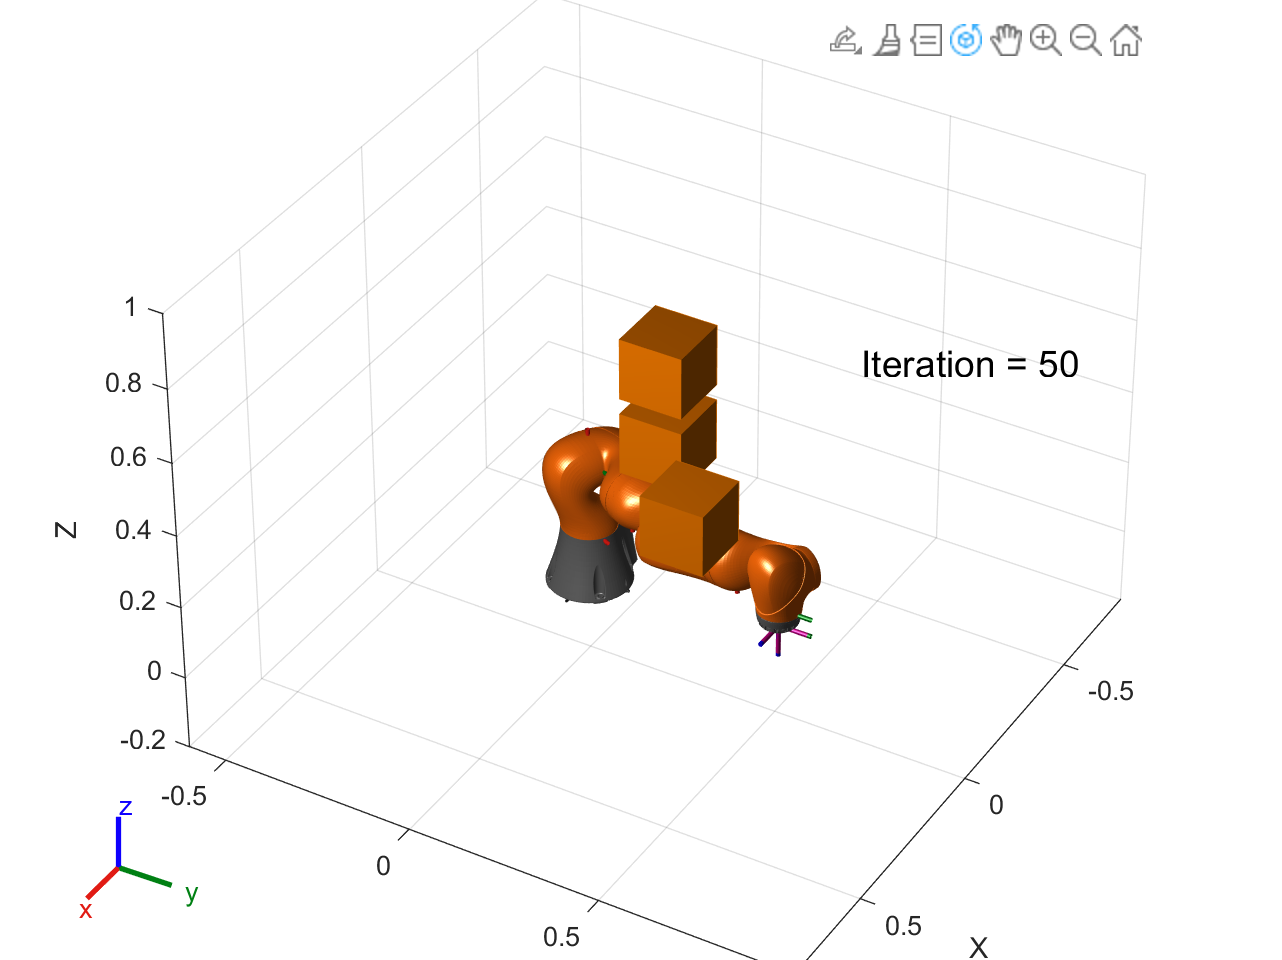

helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.